# Basic Optimization Methods

In this exercise, you are going to learn how to implement one of three optimization learned in class. Choose between the Golden Section Method, Quadratic Interpolation Method and the Random Search Method.

clear; 

## Golden Section Search Method

If you choose this method, you have an opportunity to get a maximum score of 20/20. Here are the steps:

#### 1. The Initial Guesses

The method starts with two initial guesses, $x_l$ and $x_u$, that bracket one local extremum of $f(x)$.

#### 2. Determination of Interior Points

Two interior points $x_1$ and $x_2$ are then chosen according to the equation


$$d = R(x_u - x_l)$$


where the golden ratio is given by


$$R = \frac{\sqrt5 - 1}{2}$$


The two interior points are expressed as $x_1 = x_l + d$    and    $x_2 = x_u - d$.

#### 3. Determination of region where maximum can be found

The function is evaluated at these two interior points. Two results can occur.

1. If $f(x_1) > f(x_2)$, then the domain of $x$ to the left of $x_2$, from $x_1$ to $x_2$, can be eliminated because it does not contain the maximum. For this case, $x_2$ becomes the new $x_l$ for the next round. 

2. If $f(x_2) > f(x_1)$, then the domain of $x$ to the right of $x_1$, from $x_1$ to $x_u$ would have been eliminated. In this case, $x_1$ becomes the new $x_u$ for the next round. 

Then you start over using the new values of $x_l$ or $x_u$, and repeat the process and until $x_l$ and $x_u$ converges to a single value. That single value is the value of $x$ corresponding to the maximum value of $f(x)$. 

NOTE: If you’re looking for the minimum, you use $f(x_1) < f(x_2)$ in part 1 and $f(x_1) > f(x_2)$in part 2, instead.

## Quadratic Interpolation Search Method

If you choose this method, you have an opportunity to get a maximum score of 20/20.

This method takes advantage of the fact that a second-order polynomial often provides a good approximation to the shape of $f(x)$ near an optimum. (Just as there is only one straight line connecting two points, there is only one quadratic or parabola connecting three points.) The idea is to have three points that jointly bracket an optimum, fit a parabola to the points, differentiate it, set the result equal to zero, and solve for an estimate of the optimal $x$. The result would be the equation shown where $x_0$, $x_1$ and $x_2$ are the initial guesses, and $x_3$ is the value of $x$ that corresponds to the maximum value of the quadratic fit to the guesses. 

The equation we are going to use for this method is given by


$$x_3 = \frac{f(x_0)(x_1^2-x_2^2)+f(x_1)(x_2^2-x_0^2)+f(x_2)(x_0^2-x_1^2)}{2f(x_0)(x_1-x_2)+2f(x_1)(x_2-x_0)+2f(x_2)(x_0-x_1)}$$


#### 1. The Initial Guesses

The method starts with initial guesses $x_0$, $x_1$ and $x_2$. 

#### 2. Determination of Interior Point, $x_3$

The interior point, $x_3$, is obtained using the above equation. Where do we place $x_3$?

The basic idea is this - three points are needed to complete a parabola. The new variable $x_3$ must always be between two points. Thus, the point that is not necessarily needed to form a parabola is removed. In the video example, $x_3 = 1.5055$. The initial guesses were $x_0 = 0$, $x_1=1$ and $x_2 = 4$. Since $x_3 = 1.5055$ is between $x_1=1$ and $x_2 = 4$, $x_0 = 0$ is removed and replaced with $x_1=1$, and $x_1$ becomes $1.5055$. 

The new guesses are now $x_0 = 1$, $x_1=1.5055$ and $x_2 = 4$. 

#### 3. Determination of region where maximum can be found

The new interior point, $x_3$, for the next iteration is computed using these new values, and the cycle is repeated until the difference between the two succeeding interior points are below a set tolerance value. You will set your own tolerance value.

## Random Search Method

If you choose this method, you have an opportunity to get a maximum score of 10/20. (*The 10/20 is NOT a typo.*)

This method is a brute force method and succeeds only because a sufficient number of guesses are made.

#### 1. The Initial Guesses

The method starts an initial guess, $x$, anywhere within the function boundary, $x_l$ and $x_u$, where $x_l$ is the lower bound and $x_u$ is the upper bound. 

#### 2. Determination of an interior point

A new guess, $x$, is obtained by multiplying a random number, $r$, between 0 and 1 by the difference in the function boundary, $x_u - x_l$, and then adding the result to $x_l$. In equation form, this is written as

$x=x_l +\left(x_u -x_l \right)r$.

The new maximum value is obtained by replacing the old $x$ with the new $x$ if the new $x$ is higher than the old $x$. Otherwise, the old $x$ is retained.

#### 3. Determination of maximum

The maximum is determined after a number of iterations. Theoretically, the more the number of iterations are, the better the guess is for the maximum value.

## Instructions

1. Choose from among the three methods above, the method you wish to use the determine both the maximum value of the function


$$f(x) = 2sin(x) - \frac{x^2}{10}$$


within the region $-5 \le x \le 4$. Use up to 2 decimal places.

2. In the field below, write down the command for letting the user input the initial guesses. Use MATLAB's $input()$ command, with appropriate prompts.

3. In the field below, write down your code for implementing the method you chose in order to solve for the maximum value. Assign the maximum values to the variable $xopt$. The optimum value must be accurate to 2 decimal places.

4. Plot the function and the location of the final guess. Add appropriate title and x- and y-labels.

## Solution to Golden Search Method

1. Choose from among the three methods above, the method you wish to use the determine both the maximum value of the function


$$f(x) = 2sin(x) - \frac{x^2}{10}$$


within the region $-5 \le x \le 4$. Use up to 2 decimal places.

2. In the field below, write down the command for letting the user input the initial guesses. Use MATLAB's $input()$ command, with appropriate prompts.

clear; clc;

xl = input("What is the lower bound guess? ");
xu = input("What is the upper bound guess? ");

3. In the field below, write down your code for implementing the method you chose in order to solve for the maximum value. Assign the maximum values to the variable $xopt$. The optimum value must be accurate to 2 decimal places.

syms x
f = @(x) 2*sin(x) - x.^2/10;

[xopt, yopt] = optimgsfun(f,xl,xu);

4. Plot the function and the location of the final guess. Add appropriate title and x- and y-labels.

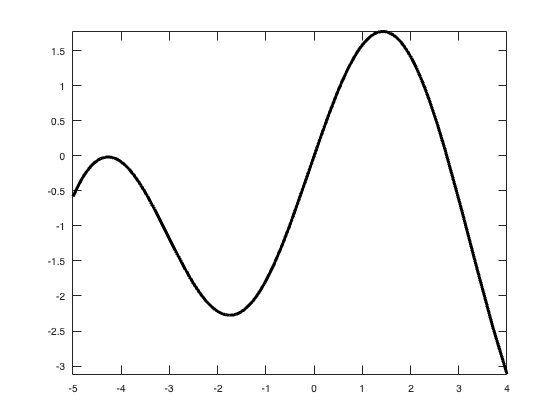

fplot(x,f,[-5 4],'k','LineWidth',3);

Use of islocalmin and islocalmax

[idxmin,yoptmin] = islocalmin(f(-5:0.1:4))

idxmin = 1×91 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


yoptmin =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.2557         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


islocalmax(double(f))

Error using matlab.internal.math.isLocalExtrema>parseInputs
First argument must be a numeric or logical array, a table, or a timetable.

Error in matlab.internal.math.isLocalExtrema (line 11)
        parseInputs(A, varargin{:});

Error in islocalmax (

Plotting the function

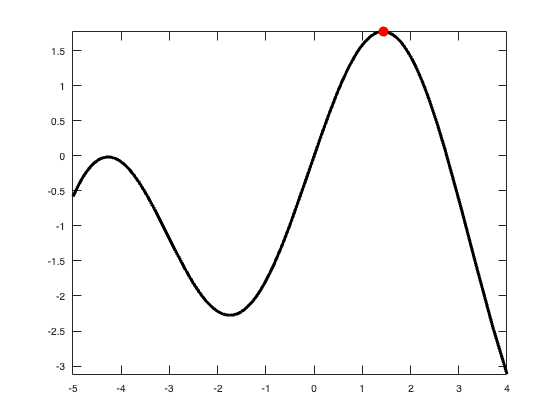

hold on
plot(xopt,yopt,'ro','MarkerSize',5,'LineWidth',5);

plot(idxmin,f(yoptmin),'bo','MarkerSize',5,'LineWidth',5)

Unrecognized function or variable 'idxmin'.

hold off
grid on
axis([-5 4 -3 2])
xlabel('x'); ylabel('f(x)');

## Solution to Quadratic Interpolation Method

1. Choose from among the three methods above, the method you wish to use the determine both the maximum value of the function


$$f(x) = 2sin(x) - \frac{x^2}{10}$$


within the region $-5 \le x \le 4$. Use up to 2 decimal places.

2. In the field below, write down the command for letting the user input the initial guesses. Use MATLAB's $input()$ command, with appropriate prompts.

clear; clc;
x0 = input("What is value of the lower bound? ");
x1 = input("What is the value of the middle point? ");
x2 = input("What is the value of the upper bound? ");

3. In the field below, write down your code for implementing the method you chose in order to solve for the maximum value. Assign the maximum values to the variable $xopt$. The optimum value must be accurate to 2 decimal places.

syms x
f = @(x) 2*sin(x) - x^2/10;

xguess = [x0 x1 x2];
[xopt, yopt] = optimquadintfun(f,xguess);

4. Plot the function and the location of the final guess. Add appropriate title and x- and y-labels.

fplot(x,f,[-5 4],'k','LineWidth',3);
hold on
plot(xopt,yopt,'ro','MarkerSize',5,'LineWidth',5);
hold off
grid on
axis([-5 4 -3 2])
xlabel('x'); ylabel('f(x)');

## Solution to Random Search Method

1. Choose from among the three methods above, the method you wish to use the determine both the maximum value of the function


$$f(x) = 2sin(x) - \frac{x^2}{10}$$


within the region $-5 \le x \le 4$. Use up to 2 decimal places.

2. In the field below, write down the command for letting the user input the initial guesses. Use MATLAB's $input()$ command, with appropriate prompts.

clear; clc;

xl = input("What is the lower bound guess? ");
xu = input("What is the upper bound guess? ");

3. In the field below, write down your code for implementing the method you chose in order to solve for the maximum value. Assign the maximum values to the variable $xopt$. The optimum value must be accurate to 2 decimal places.

n = 1000;   % number of iterations
syms x
f = @(x) 2*sin(x) - x^2/10;

xopt = (xl + xu)/2;   % initial guess within the bounds
for i = 1:n
    xnew = xl + (xu - xl)*rand();
    if f(xnew) > f(xopt)
        xopt = xnew;
    end
end

4. Plot the function and the location of the final guess. Add appropriate title and x- and y-labels.

fplot(x,f,[-5 4],'k','LineWidth',3);
hold on
plot(xopt,f(xopt),'ro','MarkerSize',5,'LineWidth',5);
hold off
grid on
axis([-5 4 -3 2])
xlabel('x'); ylabel('f(x)');